gps_data = readtable('gps.csv');

imu_data = readtable('imu.csv');

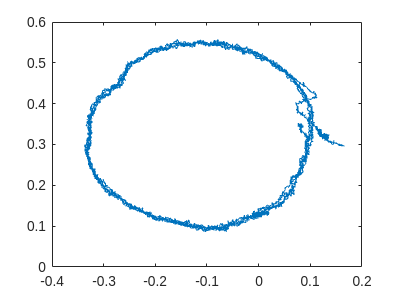


mag_x = imu_data.field_MagField_magnetic_field_x;
mag_y = imu_data.field_MagField_magnetic_field_y;

plot(mag_x,mag_y)

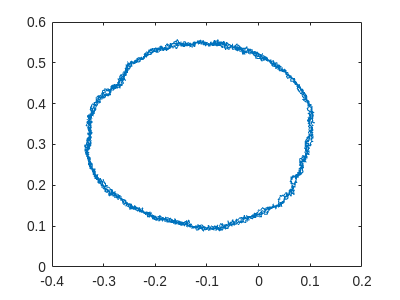

% Truncating mag_x, mag_y to remove the disturbances from the start and the
% end

mag_x(1:1000,:) = [];
mag_y(1:1000,:) = [];
len = length(mag_x);
mag_x(len-500:len,:) = [];
mag_y(len-500:len,:) = [];
plot(mag_x, mag_y)
hold on

## FITTING ELLIPSE TO THE RAW DATA

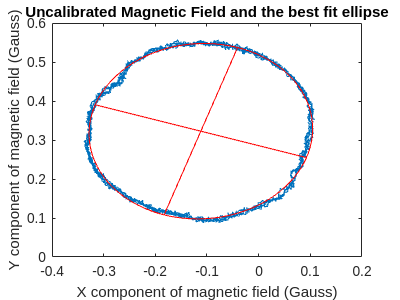

ellipse_tilted = fit_ellipse(mag_x,mag_y,1);
xlabel("X component of magnetic field (Gauss)")
ylabel("Y component of magnetic field (Gauss)")
title("Uncalibrated Magnetic Field and the best fit ellipse")
hold off

X0 = ellipse_tilted.X0;
Y0 = ellipse_tilted.Y0;
a = ellipse_tilted.a;
b = ellipse_tilted.b;
CX_t = ellipse_tilted.X0_in;
CY_t = ellipse_tilted.Y0_in;

c = cos(ellipse_tilted.phi);
s = sin(ellipse_tilted.phi);
theta = 0:0.01:2*pi;
R = [c s ; -s c];
% EX = CX_t + ellipse.a*sin(theta);
% EY = CY_t + ellipse.b*cos(theta);
% rotated_ellipse = [EX; EY];
% %plot( rotated_ellipse(1,:),rotated_ellipse(2,:),'r' );
% ver_line        = [ [X0 X0]; Y0+b*[-1 1] ];
% horz_line       = [ X0+a*[-1 1]; [Y0 Y0] ];
% new_ver_line    = R*ver_line;
% new_horz_line   = R*horz_line;
% % plot( new_ver_line(1,:),new_ver_line(2,:),'r' );
% % plot( new_horz_line(1,:),new_horz_line(2,:),'r' );




## ELIMINATING THE BIAS

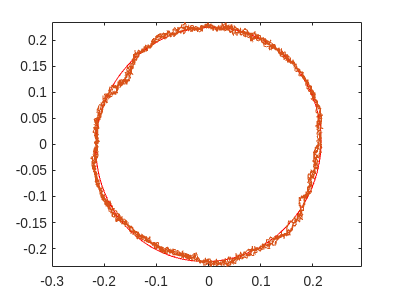

mag_x_non_bias = mag_x - CX_t;
mag_y_non_bias = mag_y - CY_t;

ellipse_shifted = fit_ellipse(mag_x_non_bias, mag_y_non_bias,1);
hold on
plot(mag_x_non_bias,mag_y_non_bias)
hold off
axis equal

## ELIMINATING THE TILT

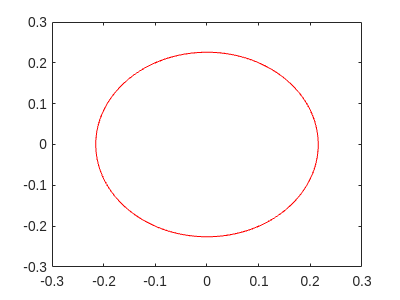

mag_non_tilt = inv(R)*[mag_x_non_bias' ; mag_y_non_bias'];
ellipse_nontilt = fit_ellipse(mag_non_tilt(1,:),mag_non_tilt(2,:),1);


a = ellipse_nontilt.a;
b = ellipse_nontilt.b;


## ELIMINIATING THE SQUISH

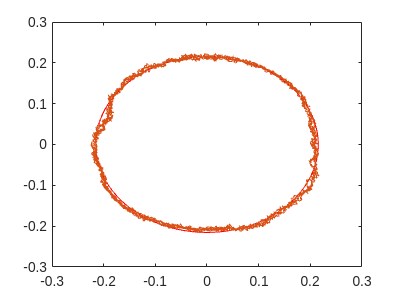

ratio = a/b;

R_squish = [1 0; 0 ratio];
mag_calibrated = R_squish*mag_non_tilt;

ellipse_calibrated = fit_ellipse(mag_calibrated(1,:),mag_calibrated(2,:),1);
hold on
plot(mag_calibrated(1,:),mag_calibrated(2,:))
hold off

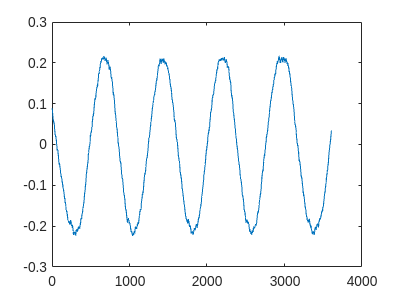


plot(mag_calibrated(1,:))

## PLOTTING THE CALIBRATED AND UNCALIBRATED MAGNETIC FIELD TOGETHER

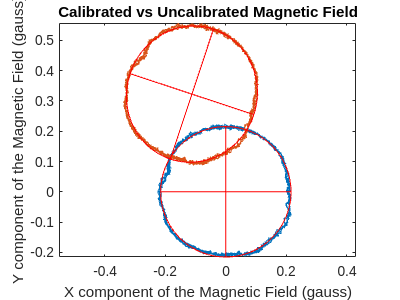

plot(mag_calibrated(1,:),mag_calibrated(2,:),"DisplayName","Calibrated Magnetic Field")
hold on
plot(mag_x,mag_y,"DisplayName","Uncalibrated Magnetic Field")
ellipse_calibrated = fit_ellipse(mag_calibrated(1,:),mag_calibrated(2,:),1);
ellipse_tilted = fit_ellipse(mag_x,mag_y,1);
hold off
xlabel("X component of the Magnetic Field (gauss)")
ylabel("Y component of the Magnetic Field (gauss)")
title("Calibrated vs Uncalibrated Magnetic Field")

axis equal

## RAW YAW

len = length(mag_x);
% raw_yaw = zeros(len,1)
% for i = 1:len
%     r = norm(mag_x(i),mag_y(i));
%     if mag_y(i) >= 0 
%         raw_yaw = -acos(mag_x(i)/r);
%     else 
%         raw_yaw = acos(mag_x(i)/r);
%     end
% end

r = (mag_x.^2 + mag_y.^2).^0.5;
raw_yaw = acos(mag_x./r)

raw_yaw =     1.4943
    1.5031
    1.5016
    1.5035
    1.5061
    1.5182
    1.5115
    1.5182
    1.5183
    1.5258


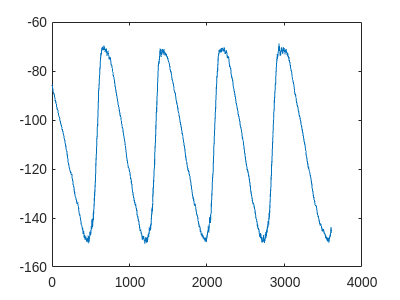

%plot((180/pi)*raw_yaw)

for i = 1:len
    if mag_y >= 0
        raw_yaw(i) = -raw_yaw(i);
    end
end
plot((180/pi)*raw_yaw)

## CALIBRATED YAW

len = length(mag_x);
yaw = zeros(len,1)

yaw =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% for i = 1:len
%     r = norm(mag_calibrated(1,i),mag_calibrated(2,i));
%     if mag_calibrated(2,i) >= 0 
%         yaw(i) = -acos(mag_calibrated(1,i)/r);
%     else 
%        yaw(i) = acos(mag_calibrated(1,i)/r);
%     end
% end
r = (mag_calibrated(1,:).^2 + mag_calibrated(2,:).^2).^0.5;
yaw = acos(mag_calibrated(1,:)./r)

yaw =     1.1464    1.1444    1.1624    1.1557    1.1672    1.1928    1.1936    1.1928    1.1995    1.2266    1.2535    1.2377    1.2644    1.2667    1.2853    1.2980    1.3010    1.2902    1.2902    1.3132    1.2918    1.2980    1.3192    1.3214    1.3013    1.3126    1.3137    1.3171    1.3214    1.3338    1.3458    1.3635    1.3681    1.3921    1.3893    1.4097    1.4269    1.4364    1.4416    1.4561    1.4704    1.4665    1.4641    1.4561    1.4693    1.4767    1.4751    1.4806    1.4783    1.4907


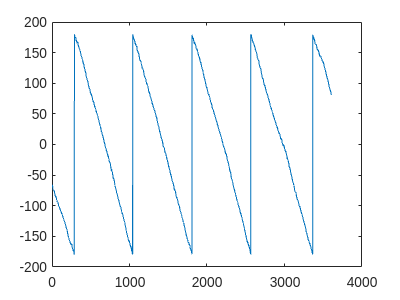

%plot((180/pi)*yaw)

for i = 1:len
    if mag_calibrated(2,i) >= 0
        yaw(i) = -yaw(i);
    end
end
plot((180/pi)*yaw)

## PLOTTING YAW

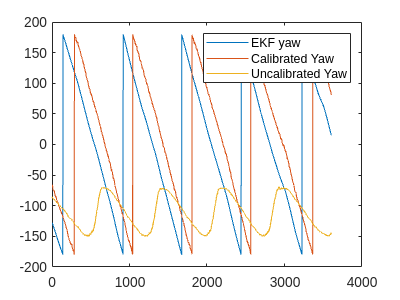

% plot(raw_yaw)
% hold on
% plot(yaw)

qx = imu_data.field_IMU_orientation_x;
qy = imu_data.field_IMU_orientation_y;
qz = imu_data.field_IMU_orientation_z;
qw = imu_data.field_IMU_orientation_w;

quat = [qw qx qy qz];
eul = quat2eul(quat);

eul(1:1000,:) = [];
len_eul = length(eul);
eul(len_eul-500:len_eul,:) = [];

yaw_EKF = (180/pi)*eul(:,1);

plot(yaw_EKF,"DisplayName","EKF yaw")
hold on
plot((180/pi)*yaw,"DisplayName","Calibrated Yaw")
plot((180/pi)*raw_yaw,"DisplayName","Uncalibrated Yaw")
legend
hold off

## INTEGRATING GYRO Z

% gyro_z = (180/pi)*imu_data.field_IMU_angular_velocity_z;
% gyro_z(1:1000) = [];
% gyro_z(length(gyro_z)-500:length(gyro_z));
% angle_z = (1/40)*cumsum(gyro_z);
% plot(angle_z);
% for i = 1:length(angle_z)
%     if angle_z(i)<=-180
%        angle_z(i:length(angle_z)) = angle_z(i:length(angle_z)) + 360; 
%     end
% end
% 
% plot(angle_z)


## MATRIX AND BIAS -SAVING PARAMETERS

Mc = R_squish*inv(R)

Mc =     0.9492   -0.3146
    0.2998    0.9045


Bc = [CX_t;CY_t]

Bc =    -0.1119
    0.3226


save('Calibration_Parameters.mat','Mc','Bc')